# Predict Responses Using RegressionEnsemble Predict Block

This example shows how to train an ensemble model with optimal hyperparameters, and then use the [RegressionEnsemble Predict](docid:stats_ug#mw_e58bdcc9-1cb9-4776-9091-d1cdf4694132) block for response prediction in Simulink®. The block accepts an observation (predictor data) and returns the predicted response for the observation using the trained regression ensemble model. 

## Train Regression Model with Optimal Hyperparameters

Load the `carbig` data set, which contains measurements of cars made in the 1970s and early 1980s.

load carbig
whos

`Origin` is a categorical variable. When you train a model for the RegressionEnsemble Predict block, you must preprocess categorical predictors by using the `dummyvar` function to include the categorical predictors in the model. You cannot use the `'CategoricalPredictors'` name-value argument. Create dummy variables for `Origin`.

c_Origin = categorical(cellstr(Origin));
d_Origin = dummyvar(c_Origin);

`dummyvar` creates dummy variables for each category of `c_Origin`. Determine the number of categories in `c_Origin` and the number of dummy variables in `d_Origin`.

unique(cellstr(Origin))
size(d_Origin)

`dummyvar` creates dummy variables for each category of `Origin`.

Create a matrix containing six numeric predictor variables and the seven dummy variables for `Origin`. Also, create a vector of the response variable.

X = [Acceleration,Cylinders,Displacement,Horsepower,Model_Year,Weight,d_Origin];
Y = MPG;

Train an ensemble using `X` and `Y` with these options:

- Specify `'OptimizeHyperparameters'` as `'auto'` to train an ensemble with optimal hyperparameters. The `'auto'` option finds optimal values for `'Method'`,`'NumLearningCycles'`, and `'LearnRate'` (for applicable methods) of `fitrensemble` and `'MinLeafSize'` of tree learners. 

- For reproducibility, set the random seed and use the `'expected-improvement-plus'` acquisition function. Also, for reproducibility of the random forest algorithm, specify `'Reproducible'` as `true` for tree learners. 

rng('default')
t = templateTree('Reproducible',true);
ensMdl = fitrensemble(X,Y,'Learners',t, ...
    'OptimizeHyperparameters','auto', ...
    'HyperparameterOptimizationOptions', ...
    struct('AcquisitionFunctionName','expected-improvement-plus'))

`fitrensemble` returns a [`RegressionBaggedEnsemble`](docid:stats_ug#bsumoso-1) object because the function finds the random forest algorithm (`'Bag'`) as the optimal method.

## Create Simulink Model

This example provides the Simulink model `slexCarDataRegressionEnsemblePredictExample.slx`, which includes the [RegressionEnsemble Predict](docid:stats_ug#mw_e58bdcc9-1cb9-4776-9091-d1cdf4694132) block. You can open the Simulink model or create a new model as described in this section.

Open the Simulink model `slexCarDataRegressionEnsemblePredictExample.slx`.

SimMdlName = 'slexCarDataRegressionEnsemblePredictExample'; 
open_system(SimMdlName)

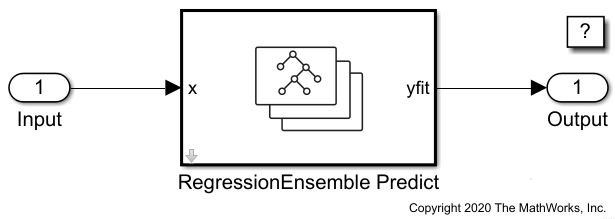

The `PreLoadFcn` callback function of `slexCarDataRegressionEnsemblePredictExample` includes code to load the sample data, train the model using the optimal hyperparameters, and create an input signal for the Simulink model. If you open the Simulink model, then the software runs the code in `PreLoadFcn` before loading the Simulink model. To view the callback function, in the **Setup** section on the **Modeling** tab, click **Model Settings** and select **Model Properties**. Then, on the **Callbacks** tab, select the `PreLoadFcn` callback function in the **Model callbacks** pane.

To create a new Simulink model, open the **Blank Model** template and add the RegressionEnsemble Predict block. Add the Inport and Outport blocks and connect them to the RegressionEnsemble Predict block. 

Double-click the RegressionEnsemble Predict block to open the Block Parameters dialog box. Specify the **Select trained machine learning model** parameter as `ensMdl`, which is the name of a workspace variable that contains the trained model. Click the **Refresh** button. The dialog box displays the options used to train the model `ensMdl` under **Trained Machine Learning Model**.

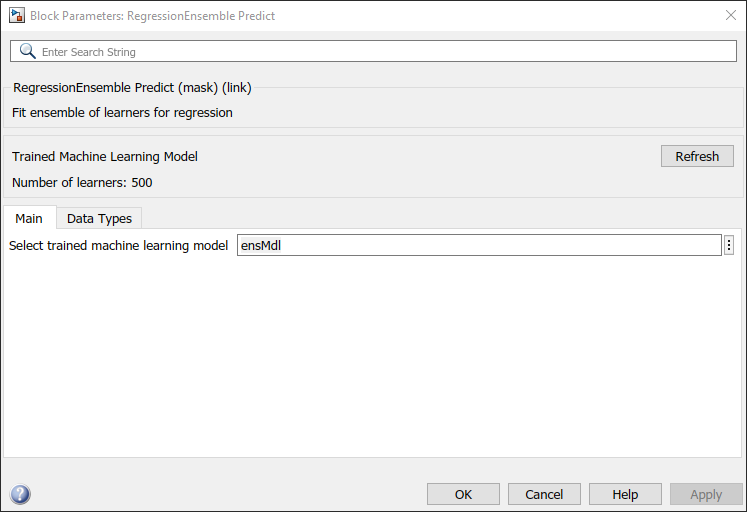

The RegressionEnsemble Predict block expects an observation containing 13 predictor values. Double-click the Inport block, and set the **Port dimensions** to 13 on the **Signal Attributes** tab.

Create an input signal in the form of a structure array for the Simulink model. The structure array must contain these fields: 

- `time` — The points in time at which the observations enter the model. The orientation must correspond to the observations in the predictor data. So, in this example, `time` must be a column vector.

- `signals` — A 1-by-1 structure array describing the input data and containing the fields `values` and `dimensions`, where `values` is a matrix of predictor data, and `dimensions` is the number of predictor variables.

Create an appropriate structure array for the `slexCarDataRegressionEnsemblePredictExample` model from the `carsmall` data set. When you convert `Origin` in `carsmall` to the `categorical` data type array `c_Origin_small`, use `categories(c_Origin)` so that `c_Origin` and `c_Origin_small` have the same number of categories in the same order.

load carsmall
c_Origin_small = categorical(cellstr(Origin),categories(c_Origin));
d_Origin_small = dummyvar(c_Origin_small);
testX = [Acceleration,Cylinders,Displacement,Horsepower,Model_Year,Weight,d_Origin_small];
testX = rmmissing(testX);
carsmallInput.time = (0:size(testX,1)-1)';
carsmallInput.signals(1).values = testX;
carsmallInput.signals(1).dimensions = size(testX,2);

To import signal data from the workspace: 

- Open the Configuration Parameters dialog box. On the **Modeling** tab, click **Model Settings**.

- In the **Data Import/Export** pane, select the **Input** check box and enter `carsmallInput` in the adjacent text box. 

- In the **Solver** pane, under **Simulation time**, set **Stop time** to `carsmallInput.time(end)`. Under **Solver selection**, set **Type** to `Fixed-step`, and set **Solver** to `discrete (no continuous states)`.

For more details, see [Load Signal Data for Simulation](docid:simulink_doccenter#import-data).

Simulate the model.

sim(SimMdlName);

When the Inport block detects an observation, it directs the observation into the RegressionTree Predict block. You can use the [Simulation Data Inspector](docid:simulink_ref#mw_df415982-8312-413a-8c53-28d643c76e75) to view the logged data of the Outport block.

*Copyright 2020 The MathWorks, Inc.*